%Circle code start here
N = 30000;
Burn_N = 1000;
for seed = 2000:1000:3000
    [cirkel_init, data, grid] = init_circle_network_and_data(seed);
    networks = metropolis_hasting(cirkel_init, N, Burn_N, 0.07, 20, data, seed, 'FULL');
    resultNetworks = random_sample(networks, N);
    plot_circle_bayes(resultNetworks, grid)
    confidence_classify_circle(resultNetworks, 0.75)
end

% Triangle code starts here
N = 30000;
Burn_N = 1000;
for seed = 2000:1000:3000
    [driehoek_init, data, grid] = init_driehoek_network_and_data(seed);
    networks = metropolis_hasting(driehoek_init, N, Burn_N, 0.05, 20, data, seed, 'FULL');
    resultNetworks = random_sample(networks, N);
    plot_triangle_bayes(resultNetworks, grid)
    confidence_classify_triangle(resultNetworks, 0.75)
end

burned = 0.4706

iterations = 0.4080

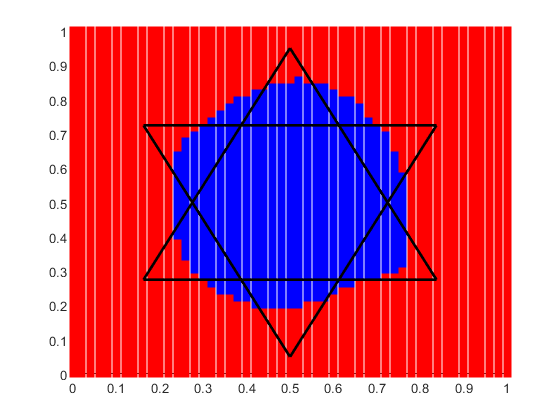

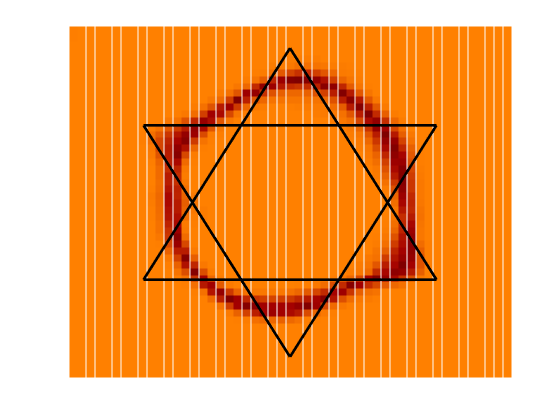

ans = 92.7336

ans = 4.4598

% Star code starts here
N = 30000;
Burn_N = 10000;
for seed = 2000
    [ster_init, data, grid] = init_ster_network_and_data(seed);
    networks = metropolis_hasting(ster_init, N, Burn_N, 0.04, 30, data, seed, 'FULL');
    resultNetworks = random_sample(networks, N);
    plot_star_bayes(resultNetworks, grid)
    confidence_classify_star(resultNetworks, 0.75)
end

function [cirkel_init, data, grid] = init_circle_network_and_data(seed)
grid = gen_grid();
corClass = correct_classify_circle(grid);

[data_XA, data_YA, data_XB, data_YB] = random_data_generator(1000, seed, "Cirkel");
data = [data_XA data_XB; data_YA data_YB; ones(1,length(data_XA)) zeros(1,length(data_XB)) ; zeros(1,length(data_XA)) ones(1,length(data_XB))];
noise_params = [0, 1];
model_params = [0, 10];
cirkel_init = NN_gen([2 5 2],"normal", model_params, seed );
cor_counter = 0;

for c = 1:length(grid)
    x = [grid(1,c); grid(2,c)];
    probs = classify(x,cirkel_init);
    if probs(1) >= probs(2)
        if corClass{c} == "A"
            cor_counter = cor_counter + 1;
        end
    else
        if corClass{c} == "B"
            cor_counter = cor_counter + 1;
        end
    end
    percent = cor_counter/length(grid);
end

iter = 0;

while percent < 0.8
    cirkel_init = train_net(cirkel_init, data, 0.35, 1000, 10, model_params, noise_params);
    iter = iter + 1;
    cor_counter = 0;
    for c = 1:length(grid)
        x = [grid(1,c); grid(2,c)];
        probs = classify(x,cirkel_init);
        if probs(1) >= probs(2)
            if corClass{c} == "A"
                cor_counter = cor_counter + 1;
            end
        else
            if corClass{c} == "B"
                cor_counter = cor_counter + 1;
            end
        end
        percent = cor_counter/length(grid);
    end
end
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

function sample = random_sample(network_input, N)

sample = cell(1,N/150);
indexes = randperm(N,N/150);
for ind = 1:length(indexes)
    sample{1,ind} = network_input{1,indexes(ind)};
end
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

function percentage_correct = plot_circle_bayes(network_input, grid)
x_vec = cell(1,length(grid));
y_vec = cell(1,length(grid));
colorvector = [];

class_vec = [];

% Classify all data points and assign unceratinty
for i = 1:length(grid)
    x = [grid(1,i); grid(2,i)];
    out = bayesian_classify(x, network_input);
    x_vec{1,i} = grid(1,i);
    y_vec{1,i} = grid(2,i);
    u = abs(out(1)-out(2));
    class_vec = [class_vec;u];
    base = [0.5 0.1 0];
    r =    [0.5*u 0 0];
    g =    [0 0.7*u-0.3 0];
    colorvector = [colorvector; (base + r + g)];
end

grid = gen_grid();

corClass = correct_classify_circle(grid);
cor_counter = 0;

XA = {};
YA = {};
XB = {};
YB = {};

for c = 1:length(grid)
    x = [grid(1,c); grid(2,c)];
    probs = bayesian_classify(x,network_input);
    if probs(1) >= probs(2)
        XA = [XA, grid(1,c)];
        YA = [YA, grid(2,c)];
        if corClass{c} == "A"
                cor_counter = cor_counter + 1;
        end
    else
        XB = [XB, grid(1,c)];
        YB = [YB, grid(2,c)];
        if corClass{c} == "B"
                cor_counter = cor_counter + 1;
        end
    end
end

XA = cell2mat(XA);
YA = cell2mat(YA);
XB = cell2mat(XB);
YB = cell2mat(YB);

th = 0:pi/50:2*pi;
xunit = 0.4 * cos(th) + 0.5;
yunit = 0.4 * sin(th) + 0.5;

figure
hold on
axis([0 1 0 1])
scatter(XA,YA,80,'blue','filled','s')
scatter(XB,YB,80,'red','filled','s')
plot(xunit,yunit,'black','LineWidth',1.5);
hold off

percentage_correct = (cor_counter/length(grid)) * 100;

% Plot uncertaintys using a color gradient
figure
hold on
axis([0 1 0 1])

x_vec = cell2mat(x_vec);
y_vec = cell2mat(y_vec);
scatter(x_vec,y_vec,80,colorvector,'filled','s')

th = 0:pi/50:2*pi;
xunit = 0.4 * cos(th) + 0.5;
yunit = 0.4 * sin(th) + 0.5;
plot(xunit,yunit,'black','LineWidth',1.5);

color = 'none';
set(gca,'XColor',color,'YColor',color,'TickDir','out')

hold off

end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

function percentage_wrong = confidence_classify_circle(network_input, confidence)
% Accept only classifications that are made with a given confidence

grid = gen_grid();
corClass = correct_classify_circle(grid);
error_counter = 0;

XA = {};
YA = {};
XB = {};
YB = {};

for c = 1:length(grid)
    x = [grid(1,c); grid(2,c)];
    probs = bayesian_classify(x,network_input);
    if probs(1) >= probs(2)
        XA = [XA, grid(1,c)];
        YA = [YA, grid(2,c)];
        if corClass{c} == "B" && probs(1) > confidence
                error_counter = error_counter + 1;
        end
    else
        XB = [XB, grid(1,c)];
        YB = [YB, grid(2,c)];
        if corClass{c} == "A" && probs(2) > confidence
                error_counter = error_counter + 1;
        end
    end
end

percentage_wrong = (error_counter/length(grid)) * 100;

end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

function percentage_correct = plot_triangle_bayes(network_input, grid)
% Uncertainty plotter
% cell(1,n) = x_co
% cell(2,n) = y_co
% cell(3,n) = uncertainty
x_vec = cell(1,length(grid));
y_vec = cell(1,length(grid));
uncert_color = [];

class_vec = [];

% Classify all data points and assign unceratinty
for i = 1:length(grid)
    x = [grid(1,i); grid(2,i)];
    out = bayesian_classify(x, network_input);
    x_vec{1,i} = grid(1,i);
    y_vec{1,i} = grid(2,i);
    u = abs(out(1)-out(2));
    class_vec = [class_vec;u];
    base = [0.5 0.1 0];
    r =    [0.5*u 0 0];
    g =    [0 0.7*u-0.3 0];
    uncert_color = [uncert_color; (base + r + g)];
end

grid = gen_grid();
corClass = correct_classify_triangle(grid);
cor_counter = 0;

XA = {};
YA = {};
XB = {};
YB = {};

for c = 1:length(grid)
    x = [grid(1,c); grid(2,c)];
    probs = bayesian_classify(x,network_input);
    if probs(1) >= probs(2)
        XA = [XA, grid(1,c)];
        YA = [YA, grid(2,c)];
        if corClass{c} == "A"
                cor_counter = cor_counter + 1;
        end
    else
        XB = [XB, grid(1,c)];
        YB = [YB, grid(2,c)];
        if corClass{c} == "B"
                cor_counter = cor_counter + 1;
        end
    end
end

XA = cell2mat(XA);
YA = cell2mat(YA);
XB = cell2mat(XB);
YB = cell2mat(YB);

xunit1 = linspace(0.1,0.9);
xunit2 = linspace(0.1,0.5);
xunit3 = linspace(0.5,0.9);
yunit1 = 0*xunit1 + 0.1;
yunit2 = 2*xunit2 - 0.1;
yunit3 = -2*xunit3 + 1.9;
 
figure
hold on
axis([0 1 0 1])
scatter(XA,YA,80,'blue','filled','s')
scatter(XB,YB,80,'red','filled','s')
plot(xunit1, yunit1,'black','LineWidth',1.5);
plot(xunit2, yunit2,'black','LineWidth',1.5);
plot(xunit3, yunit3,'black','LineWidth',1.5);
hold off

percentage_correct = (cor_counter/length(grid)) * 100;

% Plot uncertaintys using a color gradient
figure
hold on
axis([0 1 0 1])

x_vec = cell2mat(x_vec);
y_vec = cell2mat(y_vec);
scatter(x_vec,y_vec,80,uncert_color,'filled','s')


plot(xunit1, yunit1,'black','LineWidth',1.5);
plot(xunit2, yunit2,'black','LineWidth',1.5);
plot(xunit3, yunit3,'black','LineWidth',1.5);

color = 'none';
set(gca,'XColor',color,'YColor',color,'TickDir','out')

hold off
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

function percentage_wrong = confidence_classify_triangle(network_input, confidence)
% Accept only classifications that are made with a given confidence

grid = gen_grid();
corClass = correct_classify_triangle(grid);
error_counter = 0;

XA = {};
YA = {};
XB = {};
YB = {};

for c = 1:length(grid)
    x = [grid(1,c); grid(2,c)];
    probs = bayesian_classify(x,network_input);
    if probs(1) >= probs(2)
        XA = [XA, grid(1,c)];
        YA = [YA, grid(2,c)];
        if corClass{c} == "B" && probs(1) > confidence
                error_counter = error_counter + 1;
        end
    else
        XB = [XB, grid(1,c)];
        YB = [YB, grid(2,c)];
        if corClass{c} == "A" && probs(2) > confidence
                error_counter = error_counter + 1;
        end
    end
end


percentage_wrong = (error_counter/length(grid)) * 100;

end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

function [driehoek_init, data, grid] = init_driehoek_network_and_data(seed)
grid = gen_grid();
corClass = correct_classify_triangle(grid);
seed = randi(10000)
[data_XA, data_YA, data_XB, data_YB] = random_data_generator(1000, seed, "Driehoek");
data = [data_XA data_XB; data_YA data_YB; ones(1,length(data_XA)) zeros(1,length(data_XB)) ; zeros(1,length(data_XA)) ones(1,length(data_XB))];
noise_params = [0, 1];
model_params = [0, 10];
driehoek_init = NN_gen([2 4 3 2],"normal", model_params, seed );
cor_counter = 0;

for c = 1:length(grid)
    x = [grid(1,c); grid(2,c)];
    probs = classify(x,driehoek_init);
    if probs(1) >= probs(2)
        if corClass{c} == "A"
            cor_counter = cor_counter + 1;
        end
    else
        if corClass{c} == "B"
            cor_counter = cor_counter + 1;
        end
    end
    percent = cor_counter/length(grid);
end

iter = 0;

while percent < 0.8
    driehoek_init = train_net(driehoek_init, data, 0.35, 1000, 10, model_params, noise_params);
    iter = iter + 1;
    cor_counter = 0;
    for c = 1:length(grid)
        x = [grid(1,c); grid(2,c)];
        probs = classify(x,driehoek_init);
        if probs(1) >= probs(2)
            if corClass{c} == "A"
                cor_counter = cor_counter + 1;
            end
        else
            if corClass{c} == "B"
                cor_counter = cor_counter + 1;
            end
        end
        percent = cor_counter/length(grid);
    end
end
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

function [ster_init, data, grid] = init_ster_network_and_data(seed)

grid = gen_grid();
corClass = correct_classify_triangle(grid);
[data_XA, data_YA, data_XB, data_YB] = random_data_generator(1000, seed, "Ster");
data = [data_XA data_XB; data_YA data_YB; ones(1,length(data_XA)) zeros(1,length(data_XB)) ; zeros(1,length(data_XA)) ones(1,length(data_XB))];
noise_params = [0, 1];
model_params = [0, 10];
ster_init = NN_gen([2 7 5 3 2],"normal", model_params, seed );
cor_counter = 0;

for c = 1:length(grid)
    x = [grid(1,c); grid(2,c)];
    probs = classify(x,ster_init);
    if probs(1) >= probs(2)
        if corClass{c} == "A"
            cor_counter = cor_counter + 1;
        end
    else
        if corClass{c} == "B"
            cor_counter = cor_counter + 1;
        end
    end
    percent = cor_counter/length(grid);
end

iter = 0;

while percent < 0.8
    ster_init = train_net(ster_init, data, 0.35, 1000, 10, model_params, noise_params);
    iter = iter + 1;
    cor_counter = 0;
    for c = 1:length(grid)
        x = [grid(1,c); grid(2,c)];
        probs = classify(x,ster_init);
        if probs(1) >= probs(2)
            if corClass{c} == "A"
                cor_counter = cor_counter + 1;
            end
        else
            if corClass{c} == "B"
                cor_counter = cor_counter + 1;
            end
        end
        percent = cor_counter/length(grid);
    end
end

end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

function percentage_correct = plot_star_bayes(resultNetworks, grid)
% Uncertainty plotter
% cell(1,n) = x_co
% cell(2,n) = y_co
% cell(3,n) = uncertainty
x_vec = cell(1,length(grid));
y_vec = cell(1,length(grid));
uncert_color = [];

class_vec = [];

% Classify all data points and assign unceratinty
for i = 1:length(grid)
    x = [grid(1,i); grid(2,i)];
    out = bayesian_classify(x, resultNetworks);
    x_vec{1,i} = grid(1,i);
    y_vec{1,i} = grid(2,i);
    u = abs(out(1)-out(2));
    class_vec = [class_vec;u];
    base = [0.5 0.1 0];
    r =    [0.5*u 0 0];
    g =    [0 0.7*u-0.3 0];
    uncert_color = [uncert_color; (base + r + g)];
end

grid = gen_grid();
corClass = correct_classify_star(grid);
cor_counter = 0;

XA = {};
YA = {};
XB = {};
YB = {};

for c = 1:length(grid)
    x = [grid(1,c); grid(2,c)];
    probs = bayesian_classify(x,resultNetworks);
    if probs(1) >= probs(2)
        XA = [XA, grid(1,c)];
        YA = [YA, grid(2,c)];
        if corClass{c} == "A"
                cor_counter = cor_counter + 1;
        end
    else
        XB = [XB, grid(1,c)];
        YB = [YB, grid(2,c)];
        if corClass{c} == "B"
                cor_counter = cor_counter + 1;
        end
    end
end

XA = cell2mat(XA);
YA = cell2mat(YA);
XB = cell2mat(XB);
YB = cell2mat(YB);

x_tot = linspace (0.1625,0.8375);
x1 = linspace (0.1625,0.5);
x2 = linspace (0.5,0.8375);
y1 = (0*x_tot) + 0.725;
y2 = -2*x1 + 1.05;
y3 = 2*x2 - 0.95;
y4 = (0*x_tot) + 0.275;
y5 = 2*x1 - 0.05;
y6 = -2*x2 + 1.95;
  
figure
hold on
axis([0 1 0 1])
scatter(XA,YA,80,'blue','filled','s')
scatter(XB,YB,80,'red','filled','s')
plot(x_tot,y1,'black','LineWidth',2);
plot(x1,y2,'black','LineWidth',2);
plot(x2,y3,'black','LineWidth',2);
plot(x_tot,y4,'black','LineWidth',2);
plot(x1,y5,'black','LineWidth',2);
plot(x2,y6,'black','LineWidth',2);
hold off

percentage_correct = (cor_counter/length(grid)) * 100;

% Plot uncertaintys using a color gradient
figure
hold on
axis([0 1 0 1])

x_vec = cell2mat(x_vec);
y_vec = cell2mat(y_vec);
scatter(x_vec,y_vec,80,uncert_color,'filled','s')


plot(x_tot,y1,'black','LineWidth',2);
plot(x1,y2,'black','LineWidth',2);
plot(x2,y3,'black','LineWidth',2);
plot(x_tot,y4,'black','LineWidth',2);
plot(x1,y5,'black','LineWidth',2);
plot(x2,y6,'black','LineWidth',2);

color = 'none';
set(gca,'XColor',color,'YColor',color,'TickDir','out')

hold off

end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

function percentage_wrong = confidence_classify_star(resultNetworks, confidence)

% Accept only classifications that are made with a given confidence

grid = gen_grid();
corClass = correct_classify_star(grid);
error_counter = 0;

XA = {};
YA = {};
XB = {};
YB = {};

for c = 1:length(grid)
    x = [grid(1,c); grid(2,c)];
    probs = bayesian_classify(x,resultNetworks);
    if probs(1) >= probs(2)
        XA = [XA, grid(1,c)];
        YA = [YA, grid(2,c)];
        if corClass{c} == "B" && probs(1) > confidence
                error_counter = error_counter + 1;
        end
    else
        XB = [XB, grid(1,c)];
        YB = [YB, grid(2,c)];
        if corClass{c} == "A" && probs(2) > confidence
                error_counter = error_counter + 1;
        end
    end
end

percentage_wrong = (error_counter/length(grid)) * 100;

end